datapath = ...
    {"/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK002_tio/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK003_tio/"...
    }

datapath = 1×3 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK002_tio/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK003_tio/"]}




StateYao_file = ...
    {"analysis_stateYao.mat",...
    "analysis_offset0_ROIadjusted_20221202.mat",...
    "analysis_offset0_ROIadjusted_20221202.mat"...
    }

StateYao_file = 1×3 cell array
    {["analysis_stateYao.mat"]}    {["analysis_offset0_ROIadjusted_20221202.mat"]}    {["analysis_offset0_ROIadjusted_20221202.mat"]}



summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Figure1_ACh_summary'

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Figure1_ACh_summary'


summary_files = {}


summary_files =

  0×0 empty cell array



all_epochs = [2 3 4 5 6]; % all the epochs
drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

FigureVisible = 'off'

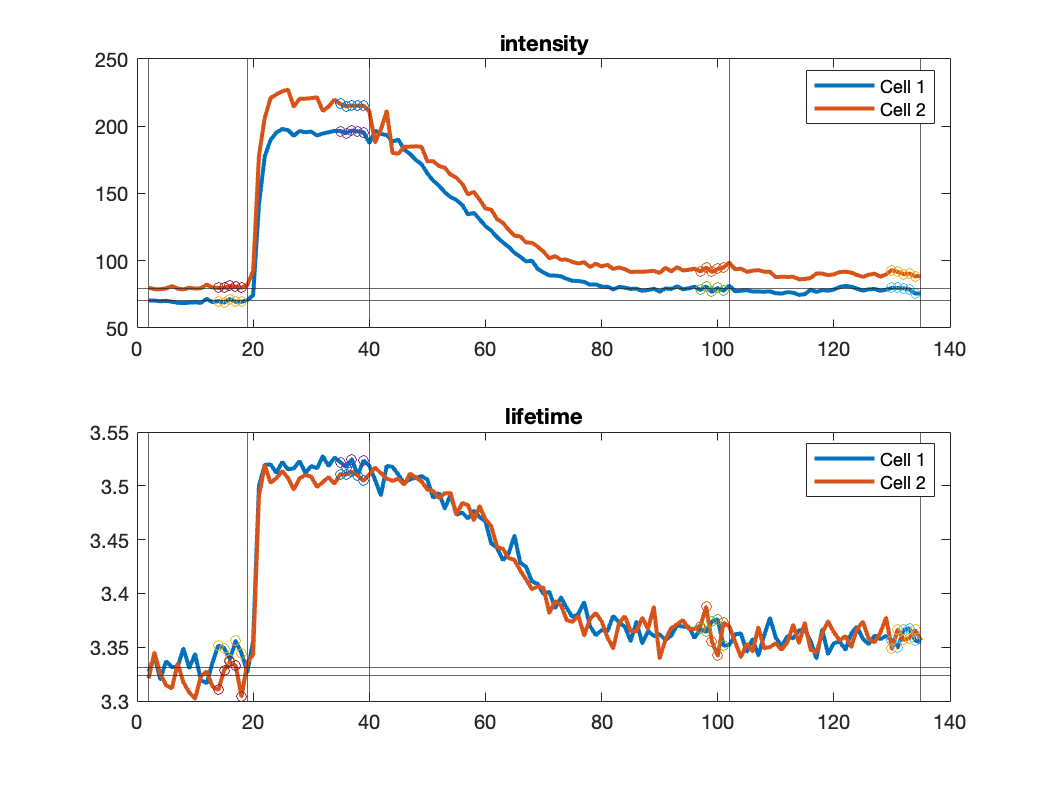

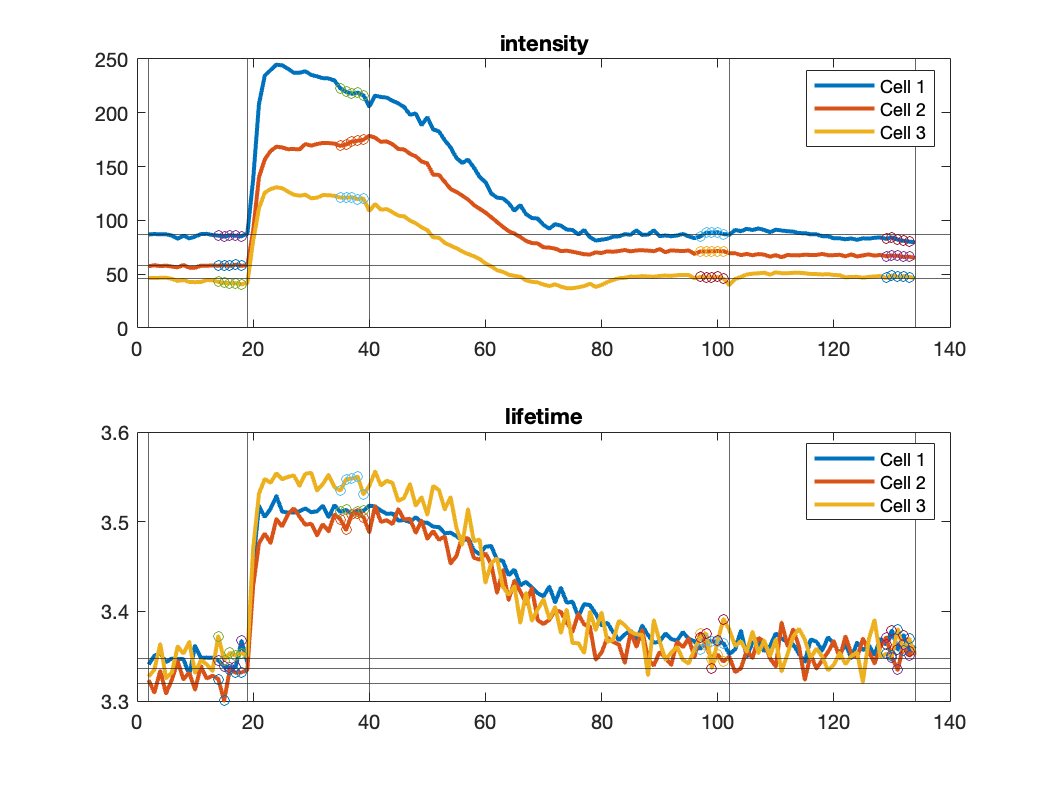

currTime = '10-Jan-2023'

epoch_response_intensity_norm_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_lft_norm_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_intensity_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_lft_all = 1×2 cell array
    {4×2 double}    {4×3 double}


for i =1:3

    cd(datapath{i});
    load(StateYao_file{i});
    
    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)
end

cd(summary_path)
load('summary_files.mat')

lft_norm_all = [];
intensity_norm_all = [];

for i = 1:length(summary_files)
    load(summary_files{i})

    for j = 1:length(epoch_response_lft_norm_all)

        lft_norm_all = [lft_norm_all epoch_response_lft_norm_all{j} NaN(4,1)];
        intensity_norm_all = [intensity_norm_all epoch_response_intensity_norm_all{j} NaN(4,1)];
    end

    lft_norm_all = [lft_norm_all NaN(4,1)];
    intensity_norm_all = [intensity_norm_all NaN(4,1)];
end


save('summary_data.mat', 'lft_norm_all', 'intensity_norm_all')



intensity1 = intensity_all{1};
intensity2 = intensity_all{2};
lft1 = lft_all{1};
lft2 = lft_all{2};

intensity1_normarlized = (intensity1 - min(intensity1))./range(intensity1);
intensity2_normarlized = (intensity2 - min(intensity2))./range(intensity2);
lft1_normarlized = (lft1 - min(lft1))./range(lft1);
lft2_normarlized = (lft2 - min(lft2))./range(lft2);

% sample trace generation
% use the cell 3 from cycle position 1 as a sample trace

AcqTime_all{1}; % timestamp
lft_all{1}(:,3); % lifetime raw ata

intensity_dfF0_c1r3 = (intensity_all{1}(:,3) - epoch_response_intensity_all{1}(1,3))/epoch_response_intensity_all{1}(1,3);

AcqTime_all{1}; % timestamp
lft_all{1}(:,2); % lifetime raw ata
intensity_dfF0_c1r2 = (intensity_all{1}(:,2) - epoch_response_intensity_all{1}(1,2))/epoch_response_intensity_all{1}(1,2);

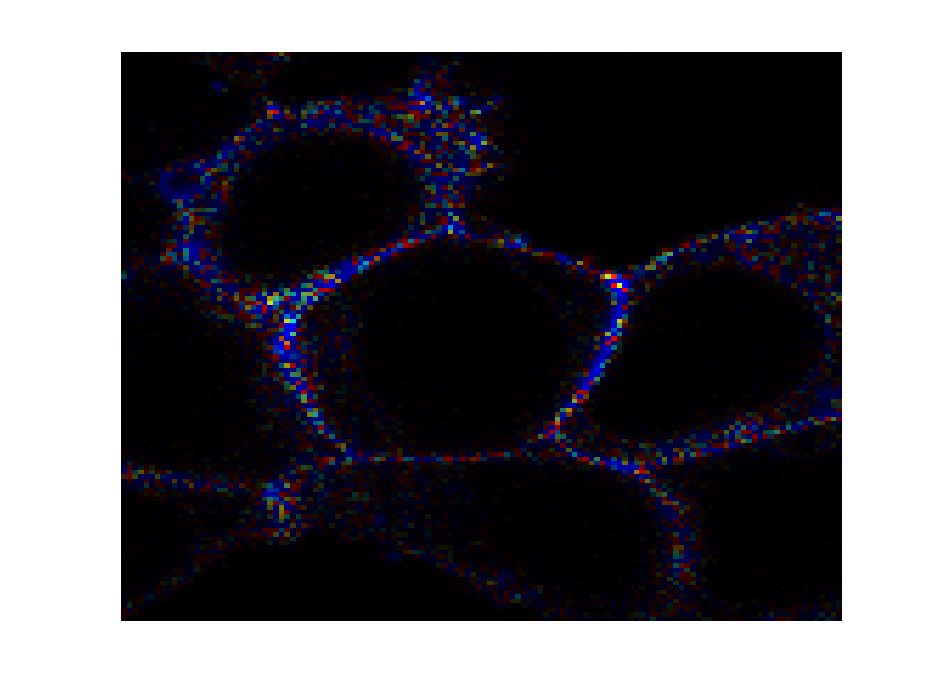

% acq = 40
chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


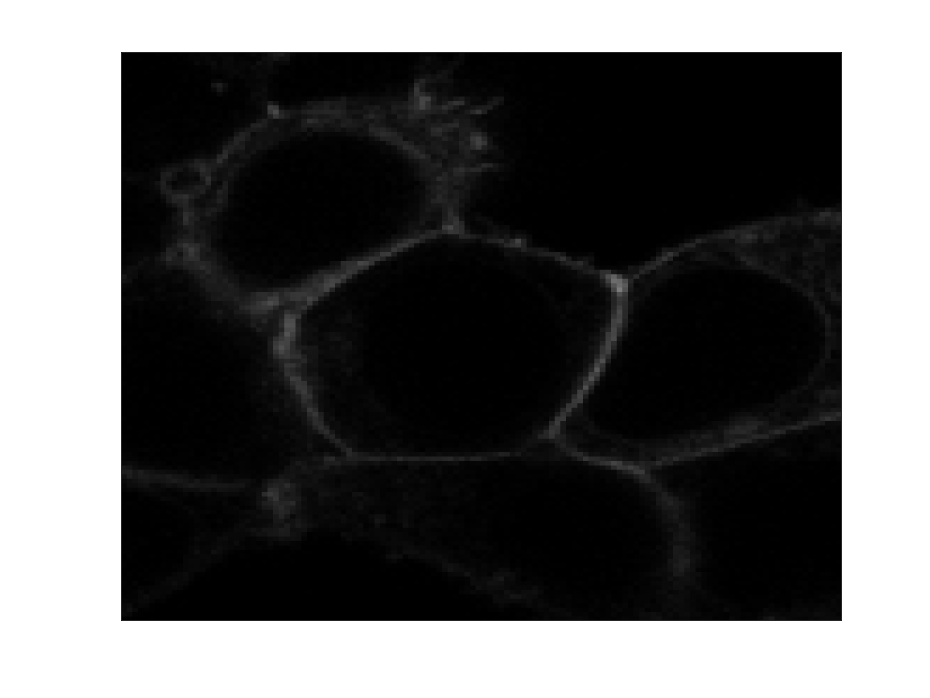

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 600];

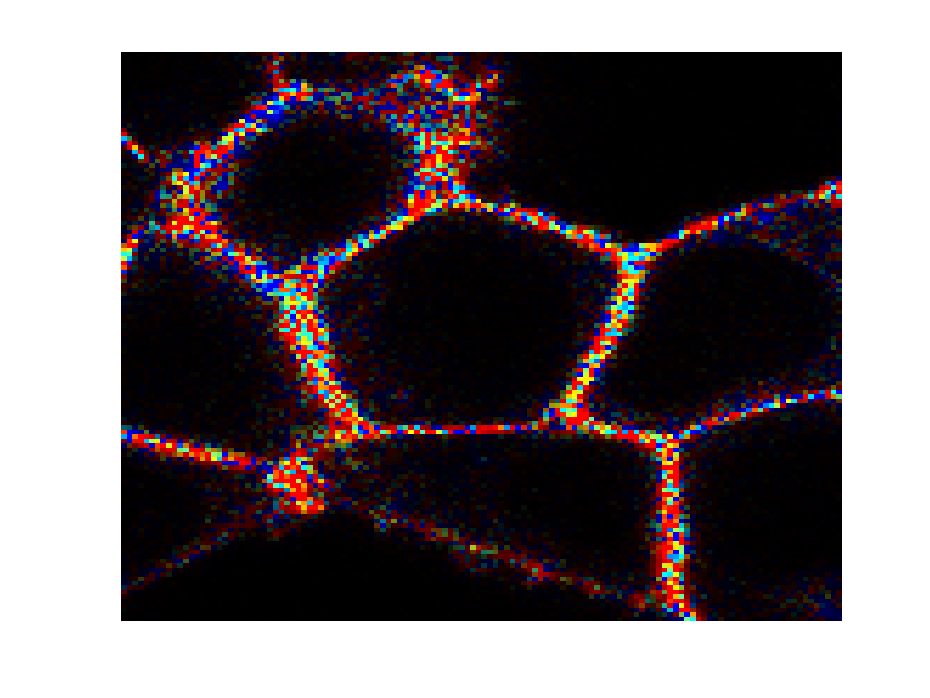

% acq = 70
chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


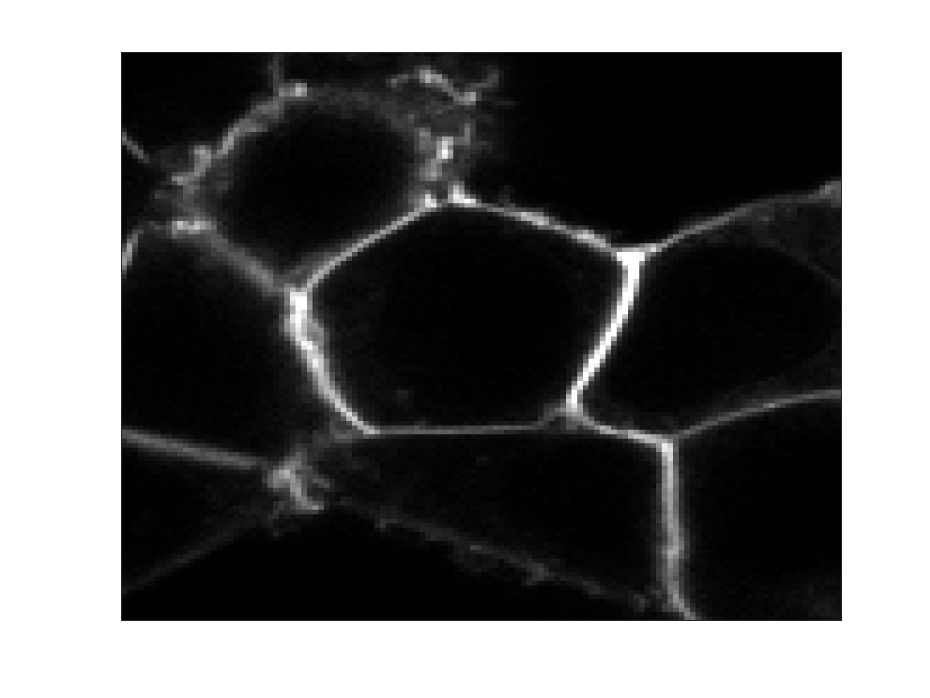

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 600];

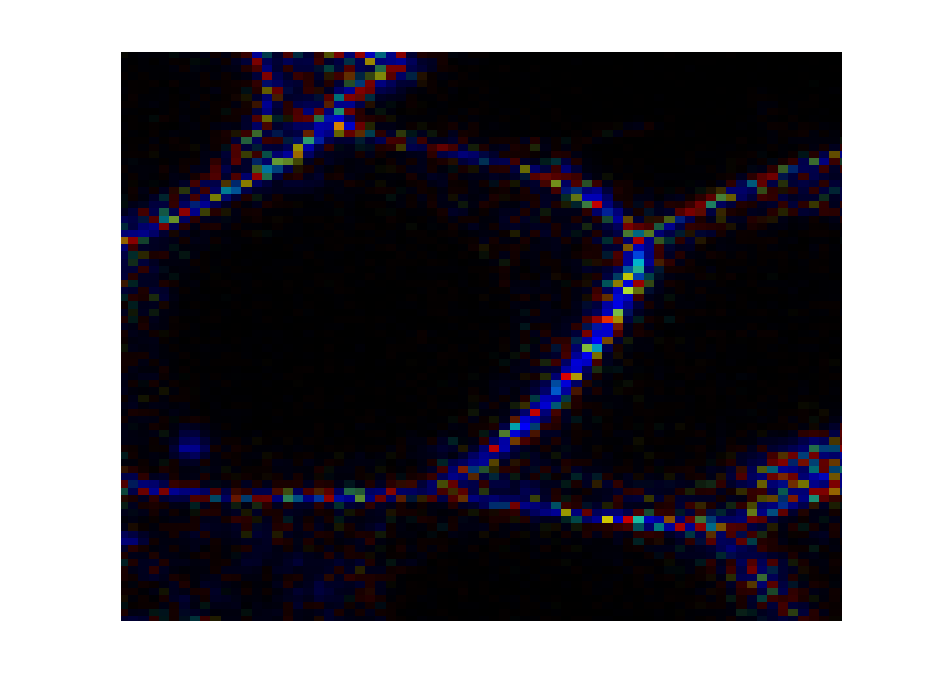

% acq = 114
chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


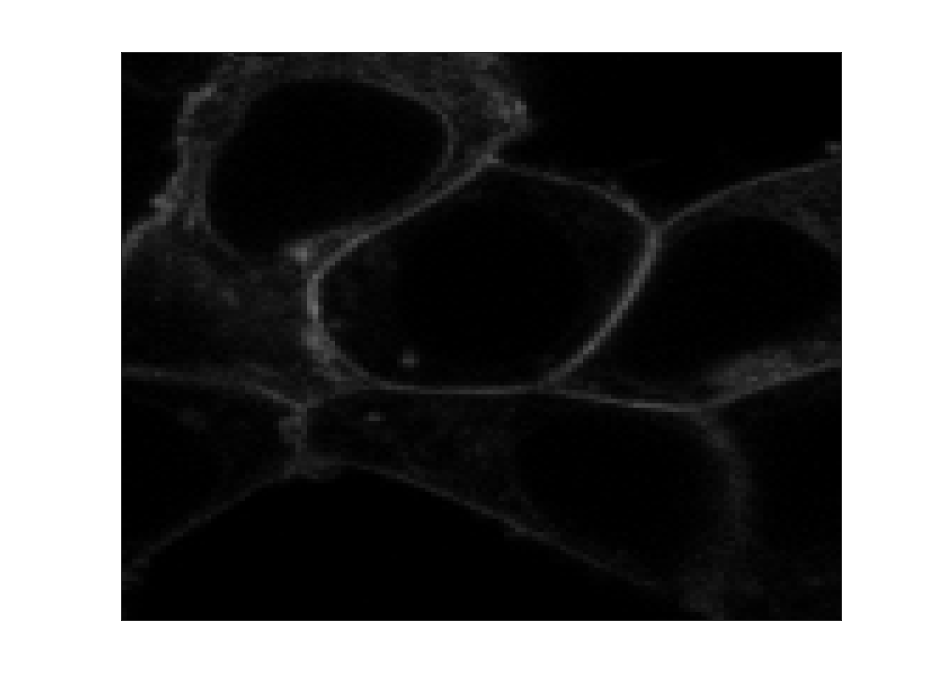

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 600];

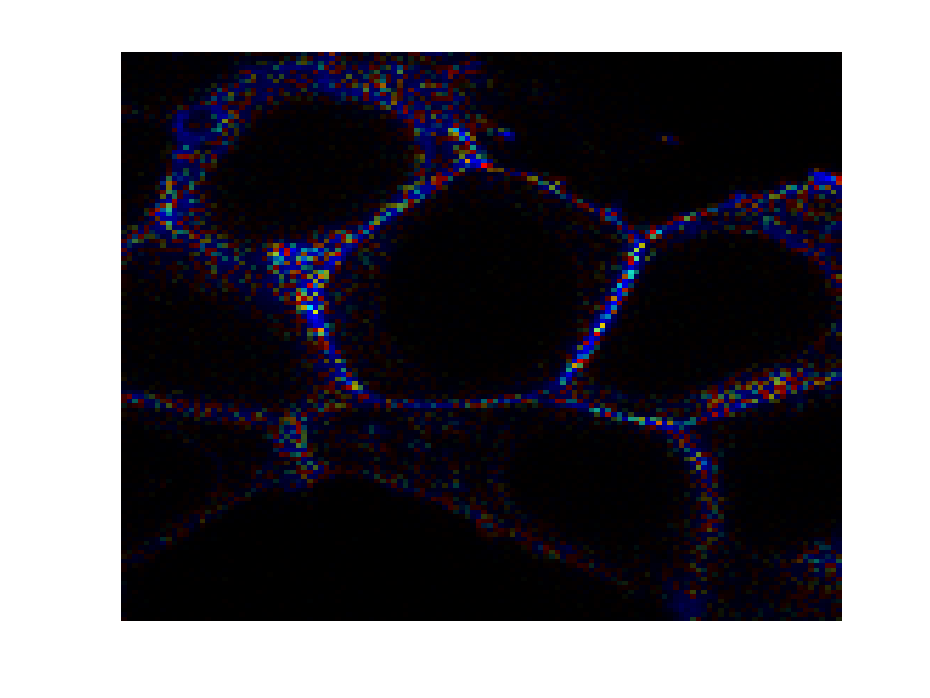

% acq = 158
chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


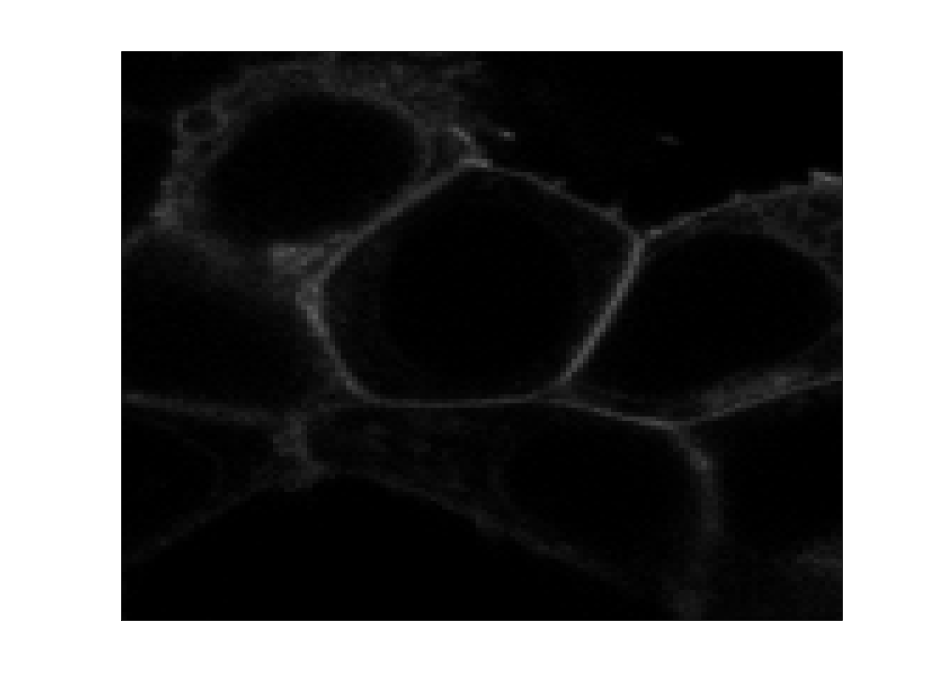

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 600];